function [signalData, responseData] = reshapeEEGdata()

# Preparing Data for Classification Training

In this livefunction, we will concatenate several EEG recordings and experiment annotations (see Figure 1 below) into a single dataset which we will use for training a classifier. Note that this workflow assumes that the data came from the Spike Recorder App from Backyard Brains (which can be downloaded [here](https://backyardbrains.com/products/spikerecorder)). However, as mentioned in the EEG_load.mlx script, it is also possible to record data from Simulink. You can view the [EEG_acquire.mlx](matlab:open('EEG_acquire.mlx')) script and can directly view the Simulink model to record data [here](matlab:open('RecordEEG.slx'))

Note that the annotation procedure and output may be different from what is demonstrated here, but the logic in preparing it for later use will remain similar.

Figure 1.) Mapping Signal Data with Response Data

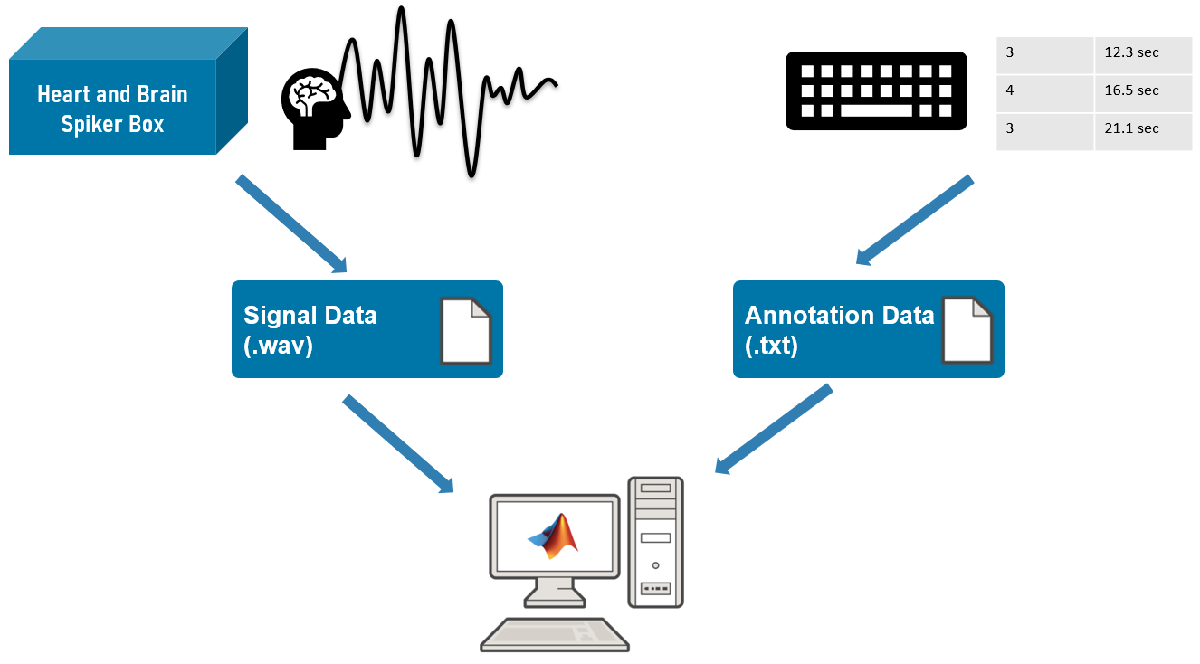

## Loading the signal data

First, we can specify which files we want to use for our experiment. Recall that after using the Backyard Brains application, we receive a .wav file that represents the collected signal, as well as an *-events.txt file that shows the annotation, where the * represents the same name as the associated signal file. Let us specify and store the names of those files:

dataFiles = ["TimBrain_VisualCortex_BYB_Recording", ...
    "BYB_Recording_2021-08-25_14.41.05", ...
    "BYB_Recording_2021-08-25_14.34.23", ...
    "BYB_Recording_2021-10-20_10.28.36"];

The files are different reference recordings hosted by BackyardBrains. It is beneficial to have various sources contributing to the dataset, as this makes the resulting classifer more robust in classifying diverse test data. 

Next, we can use the ["audioread" function](https://www.mathworks.com/help/matlab/ref/audioread.html) to load data from these files. We simply loop through each filename that we specified earlier, and in each iteration load the data and store it in our "signalData" cell array after running a bandpass filter using the ["bandpass" function](https://www.mathworks.com/help/signal/ref/bandpass.html) around the frequencies of 5-15 Hz [(alpha waves should exist at around 8 - 13 Hz in most adults)](https://www.sciencedirect.com/topics/medicine-and-dentistry/alpha-wave). If desired, you can also skip the bandpass filter if you already performed it during the data collection process itself. 

signalData = {};
for i = 1 : length(dataFiles)
    fileName = fullfile("data", dataFiles(i) + ".wav"); % create the name of the signal file by appending the file extension
    data = bandpass(audioread(fileName)', [5 15], 1e4); % run a bandpass around the interested frequencies
    signalData{i} = data;
end

At this point, "signalData" is a cell array where each entry represents the signal data (in the form of an array containing a number of type double for each time point) for each file. 

## Loading the annotation data

While loading the signal data was relatively straightforward, it takes slightly more work to load the annotation data. We want to loop through all data files, as before, but this time append "-events.txt" to get the right filename. Using the ["fopen"](https://www.mathworks.com/help/matlab/ref/fopen.html) and ["fgetl"](https://www.mathworks.com/help/matlab/ref/fgetl.html) functions to read the text file line by line, we want to ignore all lines that do not start with "3" or "4". When creating the annotation file, you can annotate with whatever key you choose. In our case, we used 3 to represent the eyes being closed, and 4 to represent them opening (note that we modified the annotation text file for the Backyard Brains reference recording to match this pattern as well).

Afterwards, we can find and isolate the time of the annotation from the rest of the line by using ["strsplit"](https://www.mathworks.com/help/matlab/ref/strsplit.html) and convert that to a number that represents the time that the annotation took place at. We store each annotation point in the "stopPoints" array. 

for i = 1 : length(dataFiles)
    stopPoints = {};
    label = "";
    fileName = fullfile("data", dataFiles(i) + "-events.txt");
    [fileID, errMsg] = fopen(fileName);
    if ~isempty(errMsg)
        error(errMsg)
    end
    tline = fgetl(fileID);
    while ischar(tline)
        if tline(1) == '3' || tline(1) == '4'
            if label == ""
                label = tline(1);
            end
            
            l = strsplit(tline);
            stopPoints{end+1} = round(str2double(l{2}) * 10000, 0);
        end
        tline = fgetl(fileID);
    end

In between annotations, we can simply label all time points to match the annotation. When we see a new annotation representing the eyes going from open to closed or vice versa, we simply switch what label we attach to all future sample points until the next annotation. 


    labels = cell(size(signalData{i}));
    for j = 1 : length(stopPoints)-1
        for k = stopPoints{j} : stopPoints{j+1} % label each time point to the proper annotation  
            labels{k} = label; 
        end
        
        % switch labels in preparation for the next annotation point
        if label == '3'
            label = '4';
        else
            label = '3';
        end
    end
    
    labels = labels(stopPoints{1}: stopPoints{end});
    

Finally, our future machine learning function calls expect these labels to be in the form of a categorical, so we can change our labels now. We also want to truncate off the unlabeled portions that would otherwise muddy our classification (the sample points before the first "3" or "4" annotations, and the points after the last "3" or "4" annotation. We do the same thing to our original signalData entries to match. 

    responseData{i} = categorical(labels); %
    % truncate te signal data to ignore the beginning and end parts without annotations
    signalData{i}  = signalData{i}(stopPoints{1}: stopPoints{end});
    fclose(fileID);
end

## Saving the data to a file

We want to save the data into a .mat file so that we can load it in the future without needing to process or even have the original .wav and .txt files generated during data collection. We can save data in our workspace to a file through the ["save"](https://www.mathworks.com/help/matlab/ref/save.html) function in MATLAB. We save the data to "EEG_data.mat"

save(fullfile("data","EEG_data.mat"), 'signalData', 'responseData');
end

© 2021 The MathWorks, Inc.